syms x1(t) x2(t) y1(t) y2(t) Y
m1 = 0.1;
m2 = 0.5;
L = 0.1;
g = 9.8;
lambda1 = 1;
lambda2 = -1;
Dx1 = diff(x1,t);
D2x1 = diff(Dx1,t);
Dy1 = diff(y1,t);
D2y1 = diff(Dy1,t);
Dx2 = diff(x2,t);
D2x2 = diff(Dx2,t);
Dy2 = diff(y2,t);
D2y2 = diff(Dy2,t);
eqn1 = m1*D2x1 + lambda2*y2 == 0

$$eqn1(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)}{10}-y_{2}\left(t\right)=0$$

eqn2 = m1*D2y1 - lambda2*x2 == 0

$$eqn2(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}y_{1}\left(t\right)}{10}+x_{2}\left(t\right)+\frac{49}{50}=0$$

eqn3 = m2*D2x2 + 2*lambda1*x2 - lambda2*y1 == 0

$$eqn3(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)}{2}+2\,x_{2}\left(t\right)+y_{1}\left(t\right)=0$$

eqn4 = m2*D2y2 + 2*lambda1*y2 + lambda2*x1 == 0

$$eqn4(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}y_{2}\left(t\right)}{2}-x_{1}\left(t\right)+2\,y_{2}\left(t\right)+\frac{49}{10}=0$$

eqn5 = x1*y2 == x2*y1

$$eqn5(t) = x_{1}\left(t\right)\,y_{2}\left(t\right)=x_{2}\left(t\right)\,y_{1}\left(t\right)$$

eqn6 = x2^2 + y2^2 == L^2

$$eqn6(t) = {x_{2}\left(t\right)}^{2}+{y_{2}\left(t\right)}^{2}=\frac{1}{100}$$

[VF,Subs] = odeToVectorField(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6)

$$VF = \left(\begin{array}{c} Y_{2}\\ -10\,Y_{5}-\frac{49}{5}\\ Y_{4}\\ 10\,Y_{7}\\ Y_{6}\\ -2\,Y_{1}-4\,Y_{5}\\ Y_{8}\\ 2\,Y_{3}-4\,Y_{7}-\frac{49}{5} \end{array}\right)$$

$$Subs = \left(\begin{array}{c} y_{1}\\ {\mathrm{Dy}}_{1}\\ x_{1}\\ {\mathrm{Dx}}_{1}\\ x_{2}\\ {\mathrm{Dx}}_{2}\\ y_{2}\\ {\mathrm{Dy}}_{2} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y})

odefcn = function_handle with value:
    @(t,Y)[Y(2);Y(5).*-1.0e+1-4.9e+1./5.0;Y(4);Y(7).*1.0e+1;Y(6);Y(1).*-2.0-Y(5).*4.0;Y(8);Y(3).*2.0-Y(7).*4.0-4.9e+1./5.0]


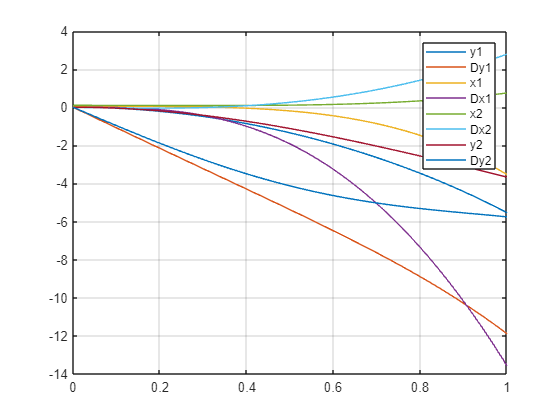

[X,Y] = ode45(odefcn, [0 1], [0 0 0.05 0 0.1 0 0 0]);
figure
plot(X, Y)
grid
legend(string(Subs))